Barabasi-Albert demo: growth, preferential attachment, and heavy-tailed degree distribution

Run this live script from the package folder so the helper functions are on the MATLAB path.

clearvars; close all; clc;

%DEMO_BA_GROWTH_AND_DEGREE Barabasi-Albert growth + heavy-tailed degrees.

rng(3);

m0 = 5;
m = 3;


Growth snapshots

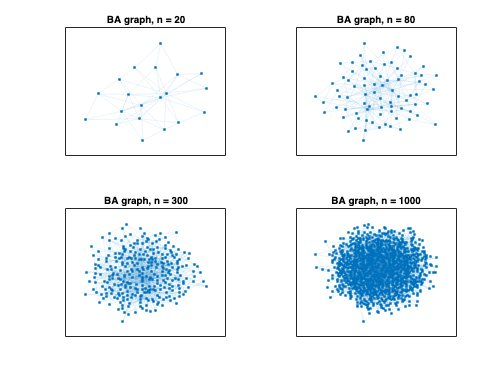

sizes = [20 80 300 1000];

figure('Name', 'BA growth snapshots');
tiledlayout(2, 2);
for i = 1:numel(sizes)
    G = make_ba_graph(sizes(i), m0, m);
    nexttile;
    plot(G, 'Layout', 'force', 'NodeLabel', {}, 'MarkerSize', 2, 'EdgeAlpha', 0.08);
    title(sprintf('BA graph, n = %d', sizes(i)));
end

Age-degree relation and degree distribution

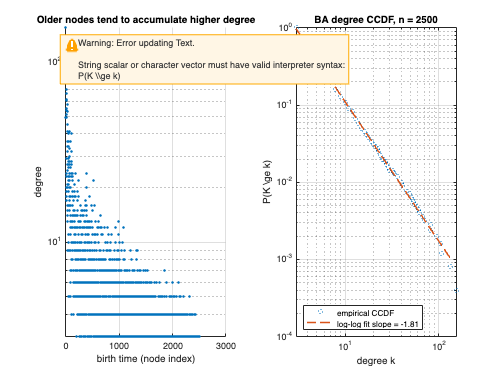

n = 2500;
G = make_ba_graph(n, m0, m);
k = degree(G);
birthTime = (1:n).';

figure('Name', 'BA rich-get-richer and degree distribution');
tiledlayout(1, 2);

nexttile;
scatter(birthTime, k, 8, 'filled');
set(gca, 'YScale', 'log');
xlabel('birth time (node index)');
ylabel('degree');
title('Older nodes tend to accumulate higher degree');
grid on;

nexttile;
[x, ccdf] = empirical_ccdf(k);
loglog(x, ccdf, 'o', 'MarkerSize', 5);
hold on;

% For a BA degree distribution with gamma ~ 3, the CCDF slope is ~ -2.
mask = (x >= m) & (ccdf > 1/n);
if nnz(mask) >= 3
    fitCoeff = polyfit(log(x(mask)), log(ccdf(mask)), 1);
    yFit = exp(polyval(fitCoeff, log(x(mask))));
    loglog(x(mask), yFit, '--', 'LineWidth', 1.6);
    legend('empirical CCDF', sprintf('log-log fit slope = %.2f', fitCoeff(1)), ...
        'Location', 'southwest');
else
    legend('empirical CCDF', 'Location', 'southwest');
end

xlabel('degree k');
ylabel('P(K \ge k)');
title(sprintf('BA degree CCDF, n = %d', n));
grid on;


fprintf('\nBA growth/degree demo finished.\n');


BA growth/degree demo finished.


fprintf('The BA model grows one node at a time and uses preferential attachment.\n');

The BA model grows one node at a time and uses preferential attachment.


fprintf('Older nodes tend to become hubs, and the degree distribution is heavy-tailed.\n\n');

Older nodes tend to become hubs, and the degree distribution is heavy-tailed.

